%clear all
close all;

%Intelligent Reflecting Surface (IRS_SEUSL)
% Main script for the IRS in differenent position and with the different
% angle with the IRS surface considering both the near field and the far field

%System parameters of the transmitting wave using HackRF
frequency = 2.4e9; %2.4GHz transmitted frquency
c=3e8; %Light velocity
wavelength = c/frequency;

% Parameters realted with IRS
Nr = 6; % No of Rows
Nc = 9; % No of Columns
num_unit_cells = Nr*Nc;
unit_cell_size=2;  %Size of the unit cell
dx = wavelength/2; % Unit cell gap

%Position of the Tx, Rx, IRS unit cells
xt=10;yt=20; %zt=10;
Position_Tx=[xt,yt]%zt];

Position_Tx =     10    20



xr=16;yr=30;%zr=10;
Position_Rx=[xr,yr]%zr];

Position_Rx =     16    30



%x_irs=10;y_irs=20;
%z_irs=10;
%z_irs = zeros(Nr, Nc);
[x_irs, y_irs] = meshgrid((0:Nc-1) * unit_cell_size, (0:Nr-1) * unit_cell_size);
%Position_IRS=[x_irs,y_irs,z_irs];

%(z_irs-zt)^2 %(z_irs-zr)^2
dt_irs = sqrt((x_irs-xt).^2 + (y_irs-yt).^2  ); % Distance from Tx to RIS unit cell
dirs_r = sqrt((xr-x_irs).^2 + (yr-y_irs).^2  ); % Distance from RIS unit cell to Rx
 

% Transmit wave characteristics
%transmit_amplitude=zeros(Nr,Nc);
transmit_phase=zeros(Nr,Nc);
for col = 1:Nc
    for row = 1:Nr
        transmit_amplitude = 1*ones(Nr,Nc);
        transmit_phase = exp(1j*2*pi*dt_irs/wavelength); % in radians   
    end
end

%wave_amplitude=transmit_amplitude;

% Reflected wave characteristics
reflected_amplitude = zeros(Nr,Nc);
reflected_phase = zeros(Nr, Nc);

for col = 1:Nc
    for row = 1:Nr
        % Each unit cell reflects the wave with its calculated phase shift
        reflected_amplitude = transmit_amplitude;
        reflected_phase = exp(1j*2*pi*dirs_r/wavelength);
        
    end
end


% Intelligent Reflecting Surface (IRS) phase shifts for beamforming
irs_phase_shifts = zeros(Nr, Nc);

% Calculate phase shifts for beamforming
for col = 1:Nc
    for row = 1:Nr
        % Calculate phase shift required for beamforming towards target (Receiver position) direction 
        phase_shift = exp(1j * (2*pi-(transmit_phase + reflected_phase)));
        % Store the phase shift
        irs_phase_shifts = angle(phase_shift); % Phase shift in radians
   end 
end


% Propagation of the wave from transmitter to IRS
dt_irs_1 = sub2ind(size(dt_irs), row, col);
[transmit_amplitude, transmit_phase] = propagate_wave(transmit_amplitude, transmit_phase, dt_irs_1, wavelength);



% Combine reflected waves from all unit cells. This is to calculate the
% received signal in the target direction in the absence of IRS is a simple
% plane surface introducing zero phase shift.

combined_signal = sum(reflected_amplitude(:).*exp(1j*reflected_phase(:)));
combined_amplitude = abs(combined_signal);
combined_phase = angle(combined_signal);

% Propagation of the  wave from IRS to receiver
dirs_r_1 = sub2ind(size(dirs_r), row, col);
[final_amplitude, final_phase] = propagate_wave(combined_amplitude, combined_phase, dirs_r_1, wavelength);
final_phase = mod(final_phase, 2 * pi); % Ensuring final phase is within [0, 2*pi]

% Output results
disp('Final received wave characteristics with zero phase shifts by IRS:');

Final received wave characteristics with zero phase shifts by IRS:


disp(['Amplitude: ', num2str(final_amplitude)]);

Amplitude: 0.0097648


disp(['Phase (radians): ', num2str(final_phase)]);

Phase (radians): 0.054819


disp(['Phase (degrees): ', num2str(rad2deg(final_phase))]);

Phase (degrees): 3.1409




% Output results
disp('Final received wave characteristics with phase compensation at IRS:');

Final received wave characteristics with phase compensation at IRS:


disp('IRS phase shifts (degrees):');

IRS phase shifts (degrees):


disp(num2str(rad2deg(irs_phase_shifts)));

-100.3781     -6.735509      2.100174      -84.9737      26.38018     -58.35291     -57.80702      28.05223     -112.3262
-50.07614      103.1275      2.060761      21.40188     -99.05072     -106.5875     -34.58595      108.8479     -71.31011
-61.14312     -49.13745     -32.98204     -88.08223     -16.39162     -1.255169     -3.113856     -10.08722     -40.98606
 35.39048     -46.85971     -4.434989    -0.3759334      5.836957      -105.492     -3.182495      85.92658      -91.6598
-14.94869      84.28335      84.81768      7.079835      34.78859     -5.752956      -17.3274     -11.43595     -29.29579
-83.67221      73.86111      64.35199     -72.97728        75.542     -112.3262       21.4071     -46.91757     -41.23116


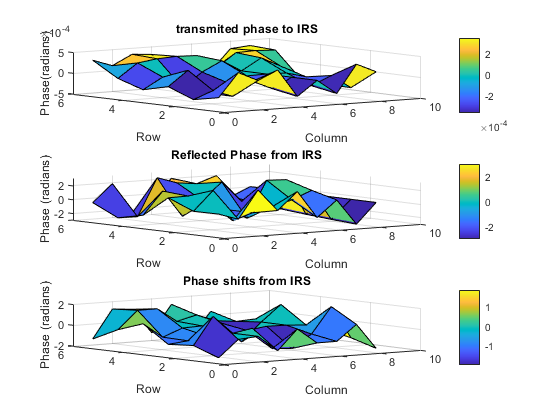


% Plotting for visualization using 3D surface plots of the phase shifts
[X, Y] = meshgrid(1:Nc, 1:Nr);

figure;
subplot(3, 1, 1);
surf(X, Y, angle(transmit_phase));
title('transmited phase to IRS');
xlabel('Column');
ylabel('Row');
zlabel('Phase(radians)');
colorbar;

subplot(3, 1, 2);
surf(X, Y, angle(reflected_phase));
title('Reflected Phase from IRS');
xlabel('Column');
ylabel('Row');
zlabel('Phase (radians)');
colorbar;

subplot(3, 1, 3);
surf(X, Y, irs_phase_shifts);
title('Phase shifts from IRS');
xlabel('Column');
ylabel('Row');
zlabel('Phase (radians)');
colorbar;

% Function definitions 

function [amplitude, phase] = propagate_wave(amplitude, phase, distance, wavelength)
    % Free space path loss model
    path_loss = (wavelength / (4 * pi * distance))^2; 
    amplitude = amplitude * sqrt(path_loss);
    phase = phase + (2 * pi * distance / wavelength); 
end

% Check the accuracy of the othe path loss models
